# Bifurcation diagram for a dumbell quantum graph with Chebyshev discretization

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

% delete .dumbbell_number  % Start with a clean slate
% rmdir data s

## Construct the quantum graph and find the first few eigenfunctions

tag='dumbbell';
Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nX',16);

nToPlot=4;
nDoubles=1;

nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);78

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);
bifurcationDiagram(tag,diagramNumber)

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);
bifurcationDiagram(tag,diagramNumber)

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\010\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `bn3` at bifurcation location` bl1(2)`

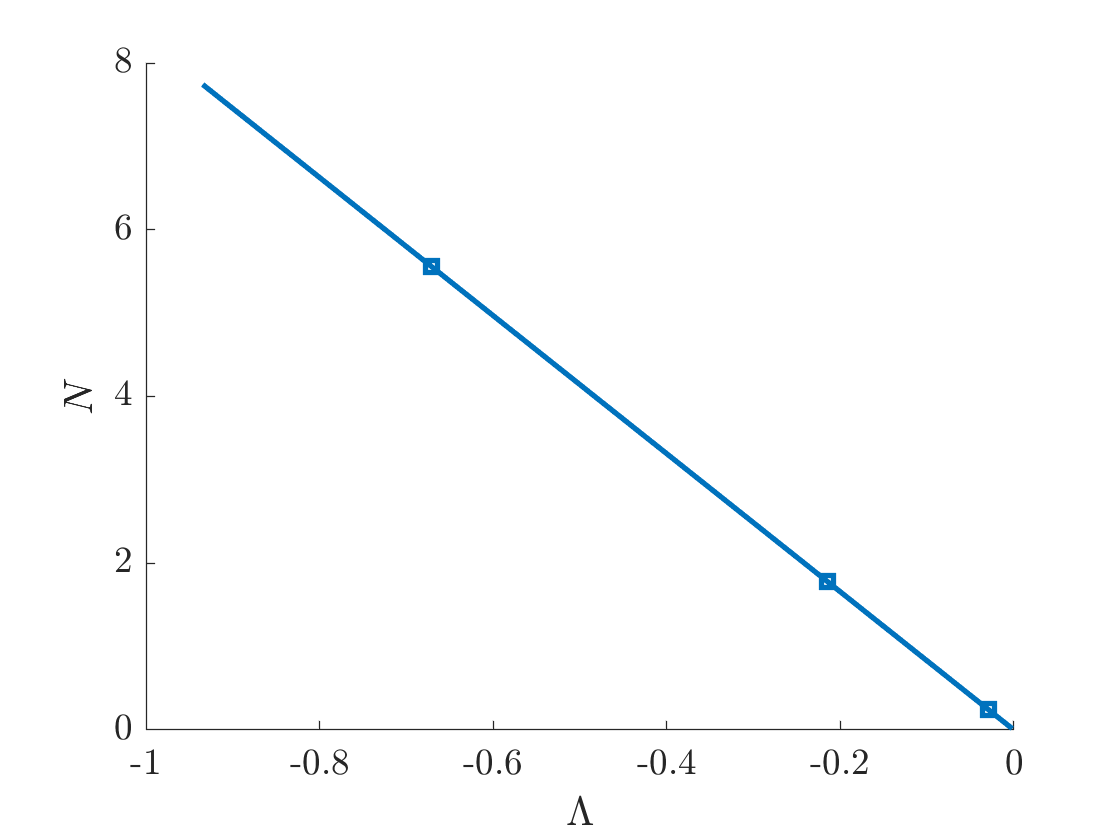

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);
bifurcationDiagram(tag,diagramNumber)

## Compute a branch that bifurcates from the third branch

Continues from the branch stored in `bn3` from the bifurcation point at `bl3(1)`

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);

N threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\010\branch002.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


bifurcationDiagram(tag,diagramNumber)

## Compute a large-amplitude solution, save it to a file, and compute its continuation

This seeds a standing wave with large frequency, localized and with positive amplitudes on edges 1 and 2.

Lambda0=-4;

Lambda threshold crossed.
Branch number 3.
Data saved to directory data\dumbbell\010\branch003.
No branching bifurcations found.


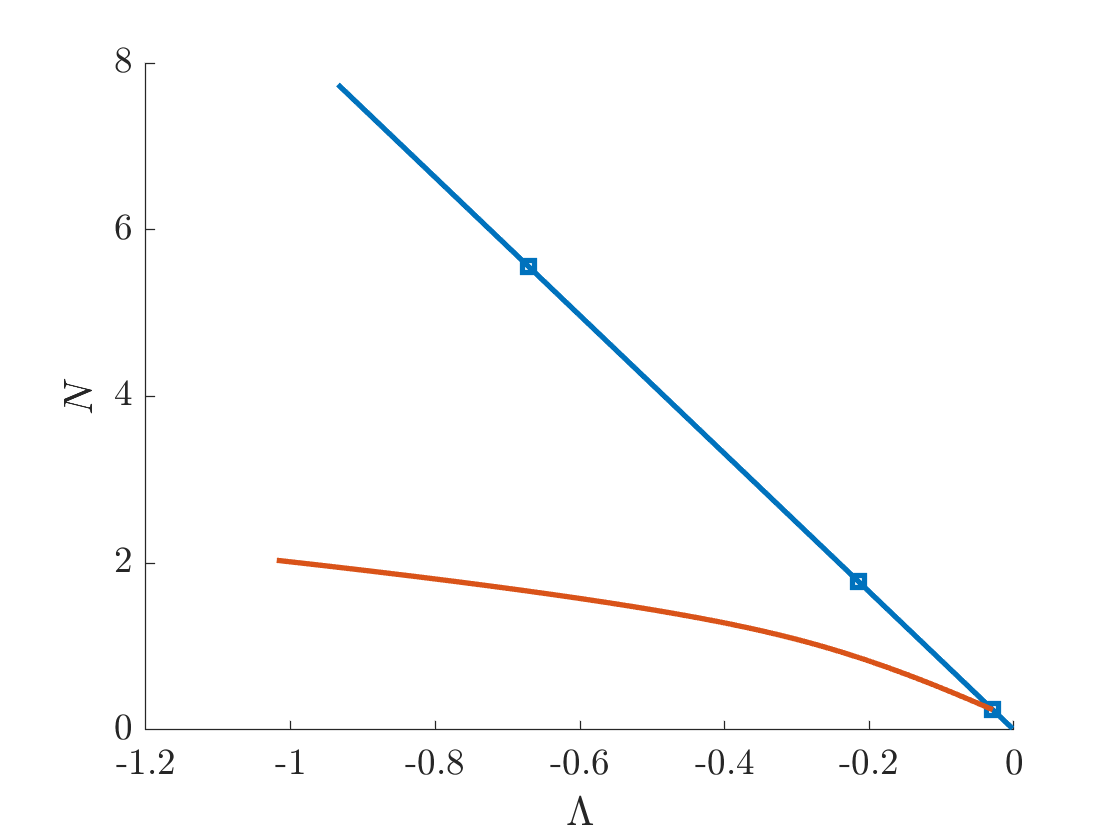

edges=[1 2];

signs=[1 1];
filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,Lambda0,edges,signs);

options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data\dumbbell\010\branch004.
Branching Bifurcation at solution number 12.


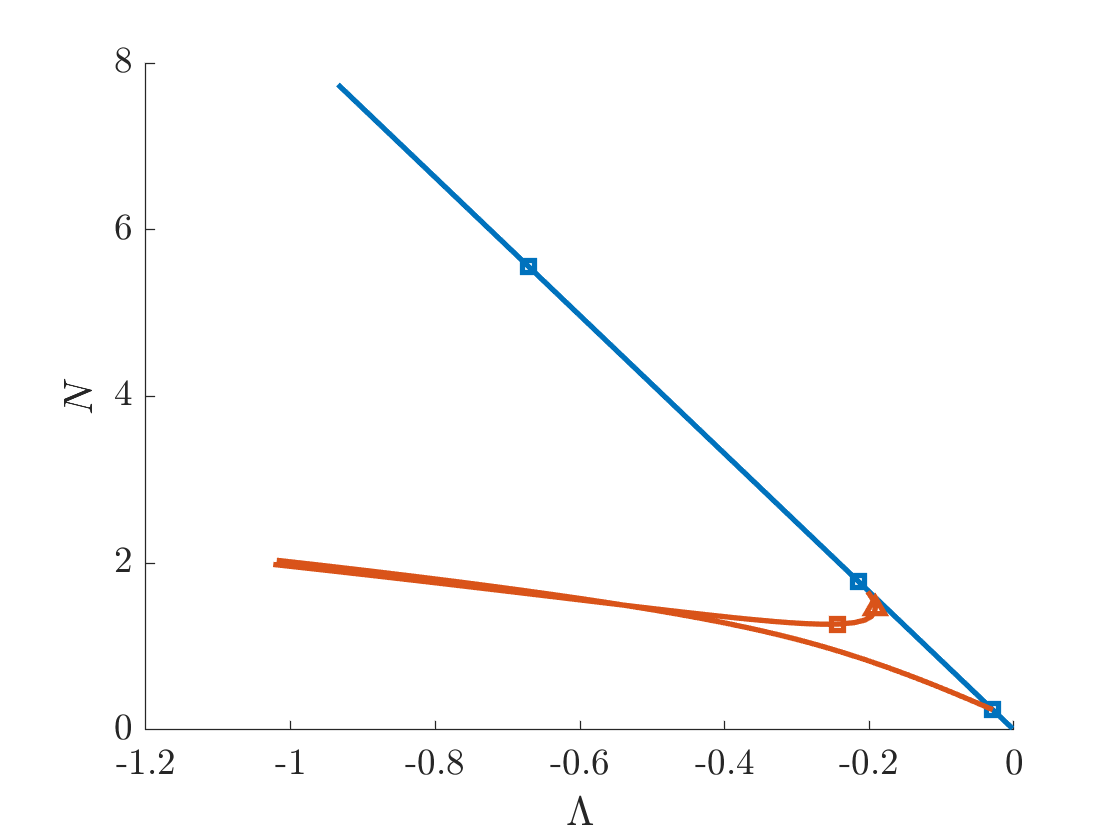

[bn6,bl6]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

bifurcationDiagram(tag,diagramNumber)

## Extend a previously-computed branch

Continuation of the branch stored in `bn1.`

NExtra=2; LambdaExtra=2;

Lambda threshold crossed.
Branch number 5.
Data saved to directory data\dumbbell\010\branch005.
No branching bifurcations found.


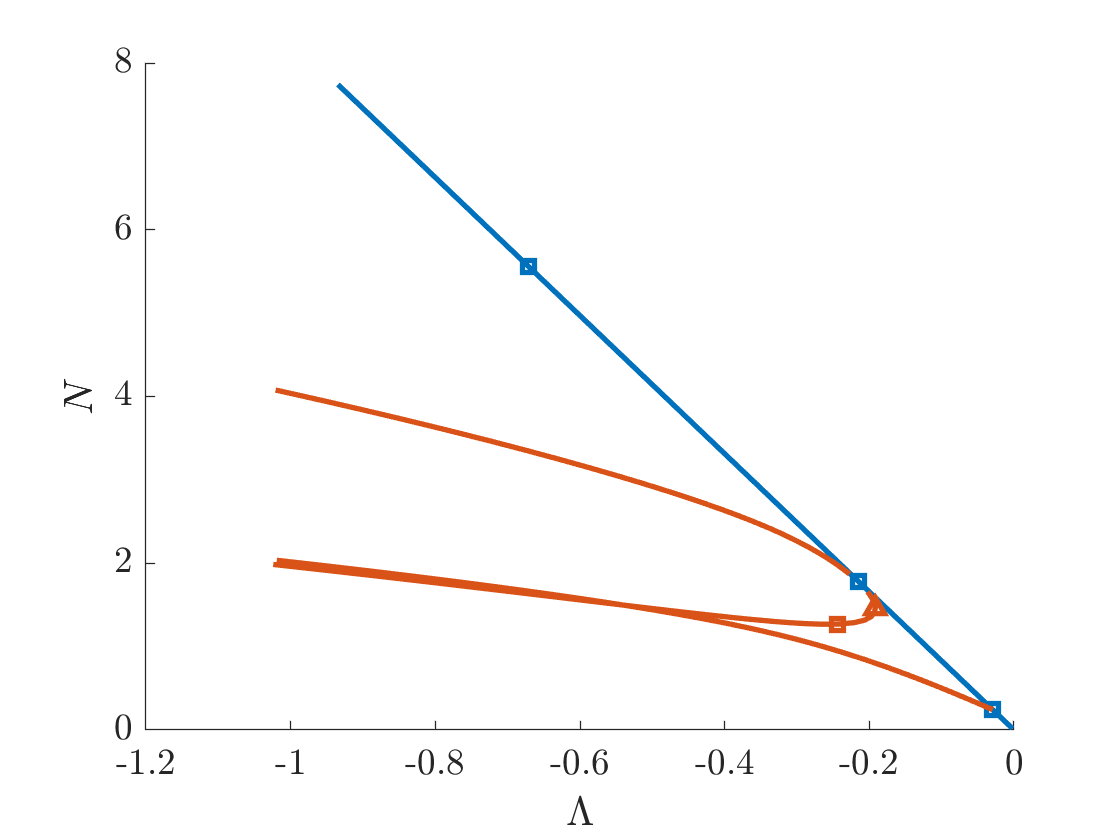

[bn7,bl7]=continueFromEnd(tag,diagramNumber,bn1,'last',NExtra,LambdaExtra,options);

bifurcationDiagram(tag,diagramNumber)

## Delete a branch

Delete a branch and it automatically disappears from the bifurcation diagram. We can remove the last computed branch

rmBranch(tag,diagramNumber,'last')

Lambda threshold crossed.
Branch number 6.
Data saved to directory data\dumbbell\010\branch006.
No branching bifurcations found.


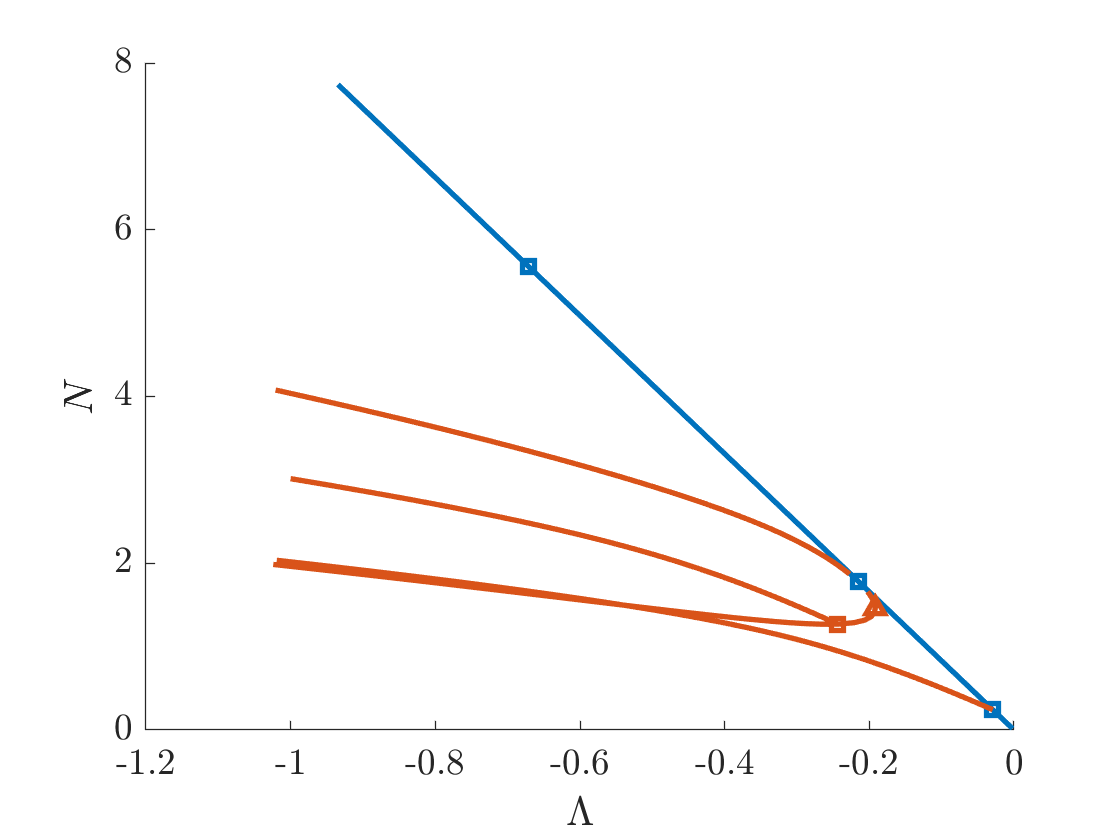

bifurcationDiagram(tag,diagramNumber)

Or else we can remove a branch by specifying the branch number:

rmBranch(tag,diagramNumber,bn5)
bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

plotSolution(tag,diagramNumber,bn3,15)

plotSolution(tag,diagramNumber,bn6,'last')

File saved to data\dumbbell\010\savedFunction.001.
File number is 1. 
